clear;
close all;
clc;

[inputSignal, fs] = audioread('noisysignal.wav');
% [noise, fs] = audioread('noise.wav');
% [signal, fs] = audioread('signal.wav');

filterOrder = 50;
cutoffFreq = 1000;
normalizedCutoff = cutoffFreq / (fs/2);

% Hamming window
window = hamming(filterOrder+1);
b_hamming = fir1(filterOrder, normalizedCutoff, window);

filteredSignalHamming = filter(b_hamming, 1, inputSignal);

H = snr(filteredSignalHamming,inputSignal-filteredSignalHamming);
disp(['SNR of FIR Hamming filtered Signal: ', num2str(H), 'dB']);

SNR of FIR Hamming filtered Signal: -7.1147dB



% Hamming window
window = hanning(filterOrder+1);
b_hanning = fir1(filterOrder, normalizedCutoff, window);

filteredSignalHanning = filter(b_hanning, 1, inputSignal);

Hn = snr(filteredSignalHanning,inputSignal-filteredSignalHanning);
disp(['SNR of FIR Hanning filtered Signal: ', num2str(Hn), 'dB']);

SNR of FIR Hanning filtered Signal: -7.1036dB



% Blackmann window
window = blackman(filterOrder + 1);
b_blackmann = fir1(filterOrder, normalizedCutoff, window);

filteredSignalBlackmann = filter(b_blackmann, 1, inputSignal);

B = snr(filteredSignalBlackmann,inputSignal-filteredSignalBlackmann);
disp(['SNR of FIR Blackmann filtered Signal: ', num2str(B), 'dB']);

SNR of FIR Blackmann filtered Signal: -6.916dB



% Kaiser window
window = kaiser(filterOrder + 1, 100);
b_kaiser = fir1(filterOrder, normalizedCutoff, window);

filteredSignalKaiser = filter(b_kaiser, 1, inputSignal);

K = snr(filteredSignalKaiser,inputSignal-filteredSignalKaiser);
disp(['SNR of FIR Kaiser filtered Signal: ', num2str(K), 'dB']);

SNR of FIR Kaiser filtered Signal: -6.078dB



% Rectangular window
window = rectwin(filterOrder + 1);
b_rect = fir1(filterOrder, normalizedCutoff, window);

filteredSignalRect = filter(b_rect, 1, inputSignal);

R = snr(filteredSignalRect,inputSignal-filteredSignalRect);
disp(['SNR of FIR Rectangular filtered Signal: ', num2str(R), 'dB']);

SNR of FIR Rectangular filtered Signal: -7.5128dB



% Bartlett window
window = bartlett(filterOrder + 1);
b_bartlett = fir1(filterOrder, normalizedCutoff, window);

filteredSignalBartlett = filter(b_bartlett, 1, inputSignal);

Bt = snr(filteredSignalBartlett,inputSignal-filteredSignalBartlett);
disp(['SNR of FIR Bartlett filtered Signal: ', num2str(Bt), 'dB']);

SNR of FIR Bartlett filtered Signal: -7.1249dB


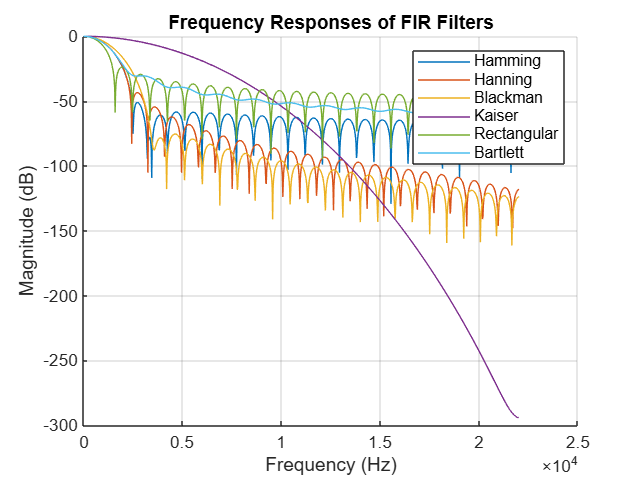


% FIR Filters
fir_filters = {
    b_hamming, 1, 'Hamming', H;  % H is SNR for Hamming
    b_hanning, 1, 'Hanning', Hn; % Hn is SNR for Hanning
    b_blackmann, 1, 'Blackman', B; % B is SNR for Blackman
    b_kaiser, 1, 'Kaiser', K; % K is SNR for Kaiser
    b_rect, 1, 'Rectangular', R; % R is SNR for Rectangular
    b_bartlett, 1, 'Bartlett', Bt; % Bt is SNR for Bartlett
};

% Frequency response for FIR filters
figure;
hold on;
snr_fir = zeros(size(fir_filters, 1), 1); % Store SNR values for bar graph
for i = 1:size(fir_filters, 1)
    b = fir_filters{i, 1};
    a = fir_filters{i, 2};
    filter_name = fir_filters{i, 3};
    snr_fir(i) = fir_filters{i, 4}; % SNR for current FIR filter
    
    [H, W] = freqz(b, a, 1024, fs); % Compute frequency response
    plot(W, 20*log10(abs(H)), 'DisplayName', filter_name);
end
hold off;
title('Frequency Responses of FIR Filters');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
legend show;
grid on;

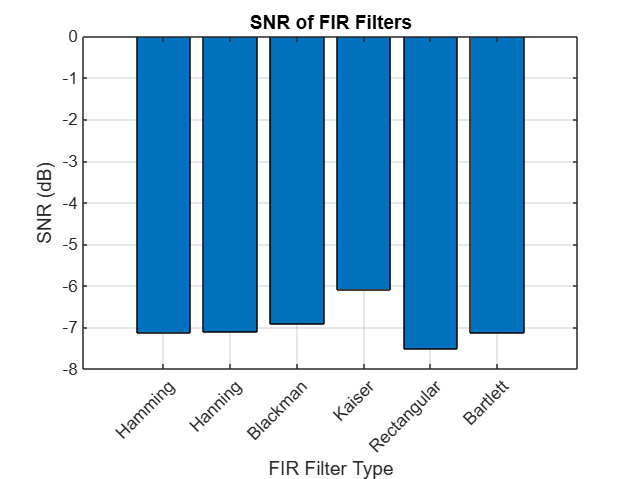


% SNR Bar Graph for FIR Filters
figure;
bar(snr_fir);
set(gca, 'XTickLabel', {fir_filters{:, 3}}, 'XTickLabelRotation', 45);
title('SNR of FIR Filters');
xlabel('FIR Filter Type');
ylabel('SNR (dB)');
grid on;


% Butterworth Filter
order=1;
[b_butterworth, a_butterworth] = butter(order, normalizedCutoff);

filteredSignalButterworth = filter(b_butterworth, a_butterworth, inputSignal);

B = snr(filteredSignalButterworth,inputSignal-filteredSignalButterworth);
disp(['SNR of IIR Butterworth filtered Signal: ', num2str(B), 'dB']);

SNR of IIR Butterworth filtered Signal: -3.6875dB



% Chebyshev Type I Filter
order=1;
ripple = 1;
[b_chebyshev1, a_chebyshev1] = cheby1(order, ripple, normalizedCutoff, 'low');

filteredSignalChebyshev1 = filter(b_chebyshev1, a_chebyshev1, inputSignal);

C1 = snr(filteredSignalChebyshev1,inputSignal-filteredSignalChebyshev1);
disp(['SNR of IIR Chebyshev1 filtered Signal: ', num2str(C1), 'dB']);

SNR of IIR Chebyshev1 filtered Signal: -2.1327dB



% Chebyshev Type II Filter
order=1;
ripple = 1;
RippleStop = 20;
[b_chebyshev2, a_chebyshev2] = cheby2(order, RippleStop, normalizedCutoff, 'low');

filteredSignalChebyshev2 = filter(b_chebyshev2, a_chebyshev2, inputSignal);

C2 = snr(filteredSignalChebyshev2,inputSignal-filteredSignalChebyshev2);
disp(['SNR of IIR Chebyshev2 filtered Signal: ', num2str(C2), 'dB']);

SNR of IIR Chebyshev2 filtered Signal: -18.4218dB



% Elliptic Filter
order=1;
ripplePass = 1;
rippleStop = 40;
[b_ellip, a_ellip] = ellip(order, ripplePass, rippleStop, normalizedCutoff);

filteredSignalElliptic = filter(b_ellip, a_ellip, inputSignal);

E = snr(filteredSignalElliptic,inputSignal-filteredSignalElliptic);
disp(['SNR of IIR Elliptic filtered Signal: ', num2str(E), 'dB']);

SNR of IIR Elliptic filtered Signal: -2.1327dB



% Bessel Filter
order=1;
[b_bessel, a_bessel] = besself(order, normalizedCutoff);

filteredSignalBessel = filter(b_bessel, a_bessel, inputSignal);

Be = snr(filteredSignalBessel,inputSignal-filteredSignalBessel);
disp(['SNR of IIR Bessel filtered Signal: ', num2str(Be), 'dB']);

SNR of IIR Bessel filtered Signal: -26.8682dB


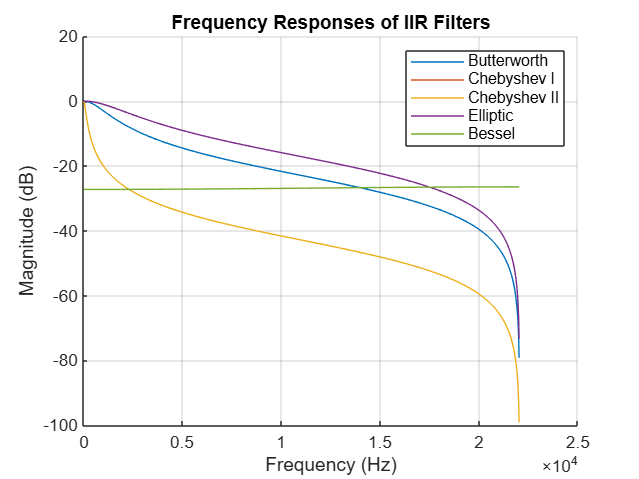


% IIR Filters
iir_filters = {
    b_butterworth, a_butterworth, 'Butterworth', B; % SNR B
    b_chebyshev1, a_chebyshev1, 'Chebyshev I', C1; % SNR C1
    b_chebyshev2, a_chebyshev2, 'Chebyshev II', C2; % SNR C2
    b_ellip, a_ellip, 'Elliptic', E; % SNR E
    b_bessel, a_bessel, 'Bessel', Be; % SNR Be
};

% Frequency response for IIR filters
figure;
hold on;
snr_iir = zeros(size(iir_filters, 1), 1); % Store SNR values for bar graph
for i = 1:size(iir_filters, 1)
    b = iir_filters{i, 1};
    a = iir_filters{i, 2};
    filter_name = iir_filters{i, 3};
    snr_iir(i) = iir_filters{i, 4}; % SNR for current IIR filter
    
    [H, W] = freqz(b, a, 1024, fs); % Compute frequency response
    plot(W, 20*log10(abs(H)), 'DisplayName', filter_name);
end
hold off;
title('Frequency Responses of IIR Filters');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
legend show;
grid on;

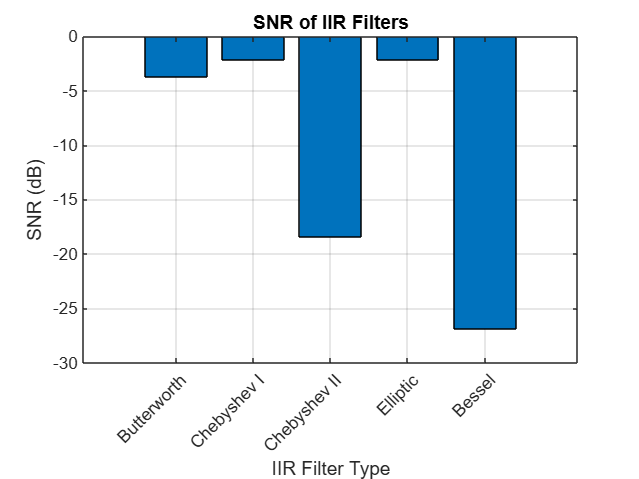


% SNR Bar Graph for IIR Filters
figure;
bar(snr_iir);
set(gca, 'XTickLabel', {iir_filters{:, 3}}, 'XTickLabelRotation', 45);
title('SNR of IIR Filters');
xlabel('IIR Filter Type');
ylabel('SNR (dB)');
grid on;